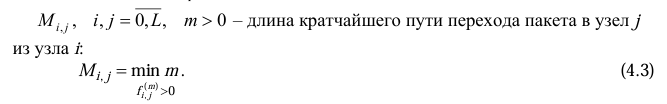

function length = find_shortest_path(P, i, j)
    n = size(P, 1);  % количество узлов
    max_steps = 100;  % максимальное количество шагов для поиска
    length = inf;  % начальная длина пути
    
    if i == j
        length = 0;  % кратчайший путь к самому себе — это 0 шагов
        return;
    end
    
    current_power = P;  % начальная степень P^1
    
    % Поиск кратчайшего пути до 100 шагов
    for m = 1:max_steps
        if current_power(i, j) > 0  % если вероятность ненулевая
            length = m;  % записываем длину пути
            break;  % выходим из цикла, так как путь найден
        end
        % Возводим матрицу в следующую степень (P^m -> P^(m+1))
        current_power = current_power * P;
    end
end